rng(14);
n=500;
% rand1 = exprnd(.16,[1,floor(n/3)]);
% rand1 = rand1(rand1<=0.6);
% rand1 = rand1(rand1>0);
% rand3 = exprnd(0.12,[1,floor(n/3)])+0.5;
% rand3 = rand3(rand3<=1);
% rand3 = rand3(rand3>0.5);
lower = 0;
peak = 0.2;
upper = 1;
pd = makedist('Triangular','A',lower,'B',peak,'C',upper);
y = random(pd,1,n);

% y = ([rand1])

% y = y(y<=1);
sum(y<0)

ans = 0

sum(y>1)

ans = 0



% d = 11;
knots = [-0.0250:0.1:1.025];
orig_knots = knots;
knots(end-1) = 1;
knots(2) = 0;
constraintFunc = @(x) logspline_constraint(knots, x);
options = optimoptions('fsolve','Display','none','TolFun', 1e-10);

flag=11;
solve_this = @(a) (constraintFunc(a));
% initial = [-2.5, log(0.25), log(0.6),log(1.4), log(2.2), log(1.5),...
%     log(2.4), log(2.1), log(1.1), ...
%     log(1.15),log(1.2),log(0.7), log(0.75), log(0.8),...
%     log(0.4),log(0.5), log(0.6), log(0.5), log(0.4), log(0.3), ...
%     -2.5];
initial = [-2.5, log(1.6),log(2.3), log(2.4),...
    log(1.6), log(0.7), log(0.6), log(0.5), -2.5];
initial_guess = fsolve(solve_this, initial, options)

initial_guess =    -2.4992    0.4746    0.8394    0.8821    0.4746   -0.3543   -0.5090   -0.6914   -2.4994




syms func2(x)
chosen_theta = initial_guess

chosen_theta =    -2.4992    0.4746    0.8394    0.8821    0.4746   -0.3543   -0.5090   -0.6914   -2.4994


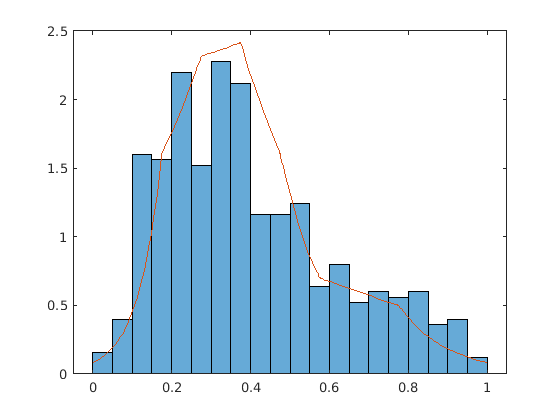

func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));
histogram(y, 'Normalization','pdf','BinWidth',0.05)
hold on
fplot(func2, [0,1])
hold off

% saveas(gcf,'InitialHist.png')


num_iters = 150000;
burn_in = 1;
proposal_scale = 1e-2

proposal_scale = 0.0100

% 
ll_function = @(x) ll_density(x, knots, y);
constraintFunc = @(x) logspline_constraint(knots, x);
dConstraintFunc = @(x) dlogspline_constraint(knots, x);
[samples, accepts] = runConstrainedMH(num_iters, burn_in, ...
    proposal_scale, initial_guess', ll_function, ...
    constraintFunc, dConstraintFunc);

The current MH ratio is: -2.317499e+00
The current MH ratio is: -1.840387e+00
Finished 250 iterations.
Calculated 70 accepts.
Current value: -3.414368e+00 -7.343324e-01 -1.411559e+00 -5.166524e-01 
The current MH ratio is: -1.566857e-01
The current MH ratio is: -1.110080e+00
Finished 500 iterations.
Calculated 146 accepts.
Current value: -3.839473e+00 5.368796e-01 -2.039483e+00 -2.912605e-01 
The current MH ratio is: 2.953338e+00
The current MH ratio is: 3.210804e-01
The current MH ratio is: -4.820932e+00
Finished 750 iterations.
Calculated 218 accepts.
Current value: -3.863189e+00 -4.619925e-01 -1.976707e+00 -4.136962e-01 
The current MH ratio is: 3.450125e-01
The current MH ratio is: -5.056927e+00
Finished 1000 iterations.
Calculated 292 accepts.
Current value: -3.166744e+00 1.772375e-01 -1.504603e+00 -1.250092e-01 
The current MH ratio is: -2.311194e+00
The current MH ratio is: -6.688943e-01
The current MH ratio is: 2.362838e+00
Finished 1250 iterations.
Calculated 371 accepts.
Curr

samples =    -2.5017   -2.6554   -2.6554   -2.5431   -2.5498   -2.5498   -2.5498   -2.6644   -2.7397   -2.7397   -2.7397   -2.7397   -2.6877   -2.6054   -2.4612   -2.4612   -2.4612   -2.5247   -2.6470   -2.6470   -2.6470   -2.6470   -2.6470   -2.6470   -2.6470   -2.6470   -2.6470   -2.6470   -2.7590   -2.7590   -2.7590   -2.7230   -2.7230   -2.7230   -2.7230   -2.7230   -2.7230   -2.7230   -2.7230   -2.7230   -2.7230   -2.7230   -2.7230   -2.7018   -2.6523   -2.6523   -2.6523   -2.5518   -2.5518   -2.5518
   -1.3919   -1.4254   -1.4254   -1.4205   -1.4801   -1.4801   -1.4801   -1.5752   -1.5597   -1.5597   -1.5597   -1.5597   -1.5707   -1.6109   -1.7081   -1.7081   -1.7081   -1.7459   -1.8204   -1.8204   -1.8204   -1.8204   -1.8204   -1.8204   -1.8204   -1.8204   -1.8204   -1.8204   -1.7738   -1.7738   -1.7738   -1.7855   -1.7855   -1.7855   -1.7855   -1.7855   -1.7855   -1.7855   -1.7855   -1.7855   -1.7855   -1.7855   -1.7855   -1.8266   -2.0227   -2.0227   -2.0227   -2.0852   -2.085

accepts =      1     0     1     1     0     0     1     1     0     0     0     1     1     1     0     0     1     1     0     0     0     0     0     0     0     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     1     0     0     0


mean(accepts)

ans = 0.3148

sum(accepts)

ans = 4722

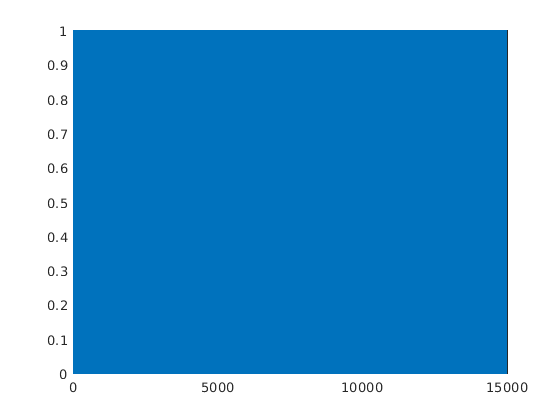

save("MH_logsplineDraws_lessknots_longrun.mat",'samples');

% plot(accepts)

% I will need to get a point estimator at some point, but for now let's
% just choose a theta and see if I can plot it.
samples = matfile("MH_logsplineDraws_lessknots_longrun.mat");
samples = samples.samples;
mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);

% fplot(y, [0,1])
[~,num_samples] = size(samples);
% character_array = ["1"];
% prev_sample = samples(:,1);
% chosen_theta = initial_guess;
% func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
%     (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
%     (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
%     (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
%     (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
%     (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
%     (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
%     (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));

Index exceeds the number of array elements (3).

% my_plot = fplot(func1, [0,1]);
% my_plot


% h = figure;
% Z = peaks;
% axis tight manual
% ax = gca;
% ax.NextPlot = 'replaceChildren';
% 
% loops = length(unique(samples(1,1:1050)));
% % num = sum(accepts)
% num = 1000;
% clear M
% M(num) = struct('cdata',[],'colormap',[]);
% 
% h.Visible = 'off';
% count = 0;
% for i = 1:num_iters
%     curr_sample = samples(:,i);
%     if ~isequal(curr_sample, prev_sample)
%         count = count + 1;
% %         character_array(end+1) = int2str(i);
% %         disp(int2str(i));
% %         disp("and");
%         disp(int2str(count));
%         prev_sample = curr_sample;
% 
%         syms func2(x)
%         chosen_theta = prev_sample;
% func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
%     (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
%     (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
%     (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
%     (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
%     (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
%     (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
%     (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));
%         fplot(func2, [0,1]);
%         ylim([0,4]);
%         hold on
%         histogram(y, 'Normalization','pdf','BinWidth',0.05)
%         hold off
%         drawnow
%         M(count) = getframe;
%         
%         if count == num
%             break
%         end
%     end
% end
% h.Visible = 'on';
% 
% movie(M);
% v = VideoWriter("traceplot");
% open(v)
% writeVideo(v,M)
% close(v)
% %
% hold on
% histogram(y, 'Normalization','pdf','BinWidth',0.01)
% %legend(character_array)
% hold off

% double(int(func1, 0, 1))
% double(int(f, 0, 1))

% all_valid = true;
% flen = length(M);
% for K = 1 : flen
%     if isempty(M(K).cdata)
%         all_valid = false;
%         str = sprintf('Empty frame occurred at frame #%d of %d\n', K, flen);
%         disp(str);
%     end
% end
% if ~all_valid
%     error('Did not write movie because of empty frames')
% end

knots = orig_knots;
knots(end-1) = 1;
knots(2) = 0;

mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);
chosen_theta = samples(:,min_index);
func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));
% my_plot = fplot(func1, [0,1]);
% set(my_plot, 'LineWidth',2);
% my_plot

[num_rows, ~] = size(samples);
upper95s = zeros(1,num_rows);
lower5s = zeros(1,num_rows);
for i=1:num_rows
    upper95s(i) = quantile(samples(i,:),0.95);
    lower5s(i) = quantile(samples(i,:),0.05);
end

histogram(y, 'Normalization','pdf','BinWidth',0.01, 'FaceColor', 'w')
chosen_theta = upper95s;
syms func1(x)
hold on
func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));
plot1 = fplot(func1, [0,1], 'LineWidth',2, 'LineStyle', "--", "Color", 'r');
% set(my_plot);

my_plot

my_plot =   handle to deleted FunctionLine


hold off


chosen_theta = lower5s;
hold on
syms func1(x)
func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));
plot2 = fplot(func1, [0,1], 'LineWidth',2, "LineStyle", "--", "Color", 'b');
% set(my_plot);
% my_plot
plot2

plot2 =   FunctionLine with properties:

     Function: [1×1 symfun]
       XRange: [0 1]
        Color: [0 0 1]
    LineStyle: '--'
    LineWidth: 2

  Show all properties


hold off
saveas(gcf,'UppersLowersNoHist.png')

saveas(gcf,'UppersLowers.png')


hold on
[~,min_index] = min(mag_mean_diff);
chosen_theta = samples(:,min_index);
syms func3(x)
func3(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));
plot3 = fplot(func3, [0,1], 'LineWidth', 2, 'Color', 'g');
plot3

plot3 =   FunctionLine with properties:

     Function: [1×1 symfun]
       XRange: [0 1]
        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 2

  Show all properties


syms tri(x)
tri(x) = piecewise( (lower <= x)&(x < peak),2*(x-lower)/((upper - lower)*(peak-lower)), ...
    (x == peak), 2/(upper-lower),...
    (peak < x)&(x <= upper),2*(upper-x)/((upper-lower)*(upper-peak)) );
plot4 = fplot(tri, [0,1], 'LineWidth', 2, "LineStyle", ":", 'Color', 'm');
plot4

plot4 =   FunctionLine with properties:

     Function: [1×1 symfun]
       XRange: [0 1]
        Color: [1 0 1]
    LineStyle: ':'
    LineWidth: 2

  Show all properties



constraintFunc = @(x) logspline_constraint(knots, x);
options = optimoptions('fsolve','Display','none','TolFun', 1e-10);
solve_this = @(a) (constraintFunc(a));
initial = [-1.3,log(double(tri(knots(3)))),log(double(tri(knots(4)))),log(double(tri(knots(5)))),...
    log(double(tri(knots(6)))), ...
    log(double(tri(knots(7)))),log(double(tri(knots(8)))), log(double(tri(knots(9)))),-1.3];
initial_guess = fsolve(solve_this, initial, options)

initial_guess =    -1.2994    0.5616    0.5967    0.4481    0.2734    0.0618   -0.2067   -0.5744   -1.2996


syms func2(x)
chosen_theta = initial_guess

chosen_theta =    -1.2994    0.5616    0.5967    0.4481    0.2734    0.0618   -0.2067   -0.5744   -1.2996


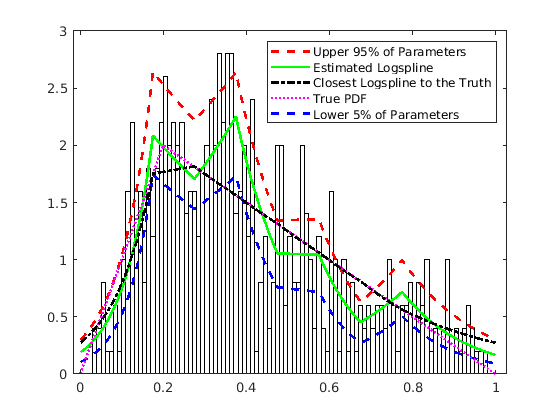

func2(x) =  piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));
plot5 = fplot(func2, [0,1], 'LineWidth', 2, "LineStyle", "-.", 'Color', 'k');

legend([plot1, plot3,plot5,plot4 plot2],'Upper 95% of Parameters','Estimated Logspline',...
    'Closest Logspline to the Truth','True PDF', 'Lower 5% of Parameters')
% legend(["this", "that", "these"])
hold off

saveas(gcf,'UppersLowersMiddle_lessknots.png')

% hold on
% histogram(y, 'Normalization','pdf','BinWidth',0.01, 'FaceColor', 'c')
% legend(character_array)
% hold off